# Project # 3: Futureskills

## FORECAST DAILY ELECTRICITY PRICES FOR HEDGING - APPLICATION OF ARIMA

Loading of data:

data1 = readtable("Electricity_ElectricityPrice.csv")

data1 = 3895×7 table
    PriceHub    TradeDate     WtdAvgPrice    Change    DailyVolumeMWh    NumberTrades    NumberCounterparties
    ________    __________    ___________    ______    ______________    ____________    ____________________

    {'ABC'}     01/05/2001       125.5          NaN          800              2                   2          
    {'ABC'}     01/08/2001       135.5           10          400              1                   2          
    {'ABC'}     01/12/2001         175         39.5          800              1                   2          
    {'ABC'}     01/19/2001         325          150          400              1                   2          
    {'ABC'}     01/26/2001         245          -80          400              1 

Creation and plotting of time-series object:

trade_date = datenum(data1.TradeDate);
time_series = timeseries(data1.WtdAvgPrice, trade_date)

  timeseries

  Timeseries contains duplicate times.

  Common Properties:
            Name: 'unnamed'
            Time: [3895x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [3895x1 double]
        DataInfo: 

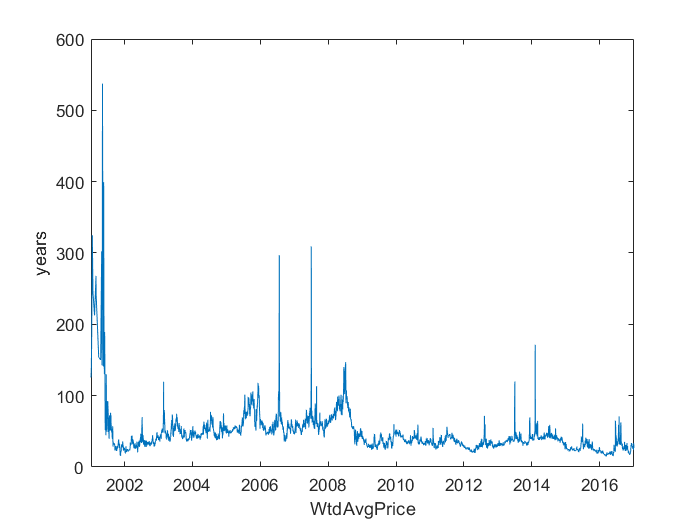

plot(data1.TradeDate, data1.WtdAvgPrice)
xlabel("WtdAvgPrice");
ylabel("years");

Check for Stationarity, Plot and interpret ACF and PACF plots to identify AR and MA orders

st_test = adftest(data1.WtdAvgPrice)

st_test = logical
   1


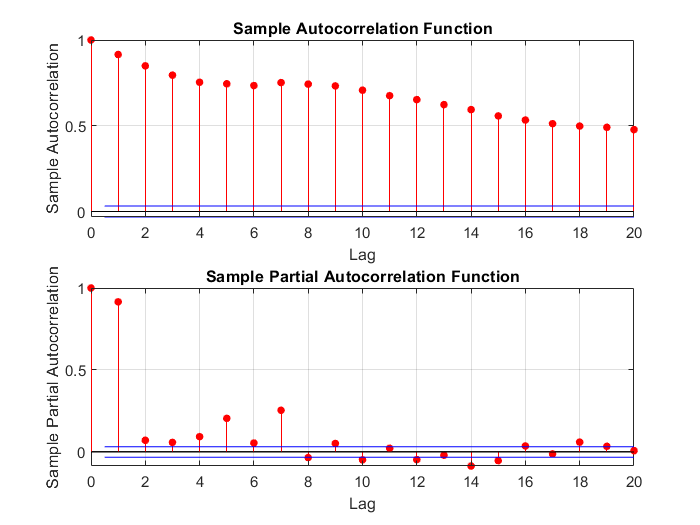

subplot(2,1,1)
autocorr(data1.WtdAvgPrice)
subplot(2,1,2)
parcorr(data1.WtdAvgPrice)

Fitting arima model was done using the econometrics toolbox.